%clc;
clear;
runtime = 40

runtime = 40

for count=1:runtime
Road_length  =100;
car_number   = count*10;
acceleration =6;
deceleration =-6.5;
density = car_number/Road_length;
%initial speed
u = 5;
%time limitis
time =1000;
%limit speed
lim = 15;

%repeat loop

%initial position of car
J = 1:car_number;
A = rand(1,car_number).*Road_length;
x(J,1) =sort(A);
v(J,1)=u;
%minimum distance between cars
x0 = Road_length/car_number;
num = car_number-1;
delT = 0.1;
k = time / delT;
%
average(1) = 0;
t(1) = 0;

for T=2:k
    for J=1:car_number
        if J == car_number
            if J==1
                dis(J,T)= Road_length;
            else
                dis(J,T) = x(1,T-1)-x(J,T-1);
            end
        else
            dis(J,T) = x(J+1,T-1)-x(J,T-1);
        end
        if dis(J,T)<0
            dis(J,T) = Road_length+dis(J,T);
        end
        if dis(J,T) > acceleration * delT
           v(J,T)=v(J,T-1) + acceleration * delT;
        elseif dis(J,T) <= v(J,T-1)
            dis(J,T)=0;
            v(J,T)=0;
        else
           v(J,T)=v(J,T-1)+ deceleration * delT;
        end
        if v(J,T)<0
            v(J,T)=0;
        end
        if v(J,T)>lim
            v(J,T)=lim;
        end
        delta_dis(J,T)=v(J,T)*delT;
        if delta_dis(J,T)>dis(J,T);
            delta_dis(J,T)=dis(J,T);
            v(J,T)=dis(J,T);
        end
        x(J,T)=x(J,T-1)+delta_dis(J,T);
        if x(J,T) > Road_length
           x(J,T)=x(J,T)- Road_length;
        end
    end
      max_speed(T) = max(v(J,T));
      min_speed(T) = min(v(J,T));
      average(T) = sum(v(:,T)) / car_number;
      averageexa(count,T) = average(T);
      t(T) = t(T-1) + delT;
end
t(T) = t(T);
x(J,T)=x(J,T);
dis(J,T)=dis(J,T);
v(J,T)=v(J,T);
average(T) = average(T)
k_1 = floor(k/3);
d_av = average(1,(k_1):k);
m = mean(d_av);
time_w = Road_length/m
end

average =          0    5.6000    6.2000    6.8000    7.4000    8.0000    8.6000    9.2000    9.8000   10.4000   11.0000   11.6000   12.2000   12.8000   13.4000   14.0000   14.6000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000


time_w = 6.6667

average =          0    5.3200    5.9200    6.5200    7.1200    7.7200    8.3200    8.9200    9.0785    9.6785    9.7602   10.2985   10.3183    9.6889   10.2889   10.8889   11.4889   11.2505   10.6738   10.1609   10.3289   10.5989   10.1746    9.6691    9.1589    9.4889    9.0989    8.7351    9.0089    8.6666    8.2956    7.9133    8.2104    7.9520    8.3420    8.7320    8.4180    8.8014    9.1914    9.5514    9.9114    9.5514    9.2716    8.9416    8.6769    9.0016    9.3916    9.8116   10.2316    9.9430


time_w = 10.3302

average =          0    4.2933    4.6867    5.0400    5.1067    5.3800    5.1800    5.1327    4.9608    4.7128    4.5528    4.8995    5.0816    5.1924    5.3234    5.3528    5.5928    6.1328    6.6728    6.8869    6.3724    6.5916    6.7832    6.9014    6.7152    6.4455    6.5330    6.7130    6.5330    6.2312    6.6730    7.1930    6.0736    6.4800    6.5200    7.0200    7.1600    6.8800    6.8800    7.3400    6.4086    6.1062    6.5686    5.8139    5.5966    5.7286    6.2286    6.0686    5.5974    6.0286


time_w = 14.5816

average =          0    4.6200    5.1900    5.7600    6.1630    6.5480    7.1330    7.0453    7.0930    6.8874    7.4032    6.8746    6.8246    6.4483    5.6605    5.1553    4.5202    4.5537    4.4158    4.2749    4.3919    4.6210    4.9589    5.4680    5.1682    5.4280    5.4246    5.9796    5.6060    5.6646    5.7430    5.6353    5.8669    5.8184    5.4567    5.7267    5.4222    5.3997    5.3244    5.5917    5.5950    5.3077    4.9453    4.6200    5.1750    5.1863    5.7150    5.7150    5.2162    5.2320


time_w = 16.3406

average =          0    4.3680    4.2123    4.5923    4.6763    4.8966    4.5913    4.5163    4.0594    3.9188    4.3403    4.8203    4.9540    5.1843    5.3883    5.2192    4.8483    5.0043    4.5123    4.3282    3.6888    3.9483    4.0947    4.3443    4.6323    4.8243    5.1360    5.3040    4.2680    4.6680    4.8240    4.7160    4.7040    4.3560    4.7040    4.5360    4.5384    4.4040    4.2720    4.5960    4.6200    4.4880    4.6560    4.4201    4.2984    4.6080    4.4640    4.6560    4.5504    5.0400


time_w = 20.5423

average =          0    3.7333    3.8703    3.7839    3.8747    3.4627    3.6185    3.4292    2.9489    3.1926    3.6626    3.5738    3.8200    3.5480    3.4887    3.4567    3.5173    3.5667    3.6567    3.5445    3.9945    3.6415    3.5529    3.8379    4.0989    4.0500    4.2255    4.3636    4.8500    4.3432    4.4691    4.4108    4.9000    4.8900    5.0300    4.8500    4.5598    4.5700    4.8300    4.4600    3.9600    4.1310    4.4700    4.6100    4.3240    4.3900    4.2400    4.3600    4.0500    4.2600


time_w = 22.3286

average =          0    3.6000    3.4404    3.1619    3.1660    3.1416    2.9142    2.5809    2.7240    2.7572    2.7114    2.8939    3.1470    3.3413    3.5534    3.5010    3.3021    3.4779    3.3710    3.1479    3.4393    3.5769    3.6563    3.7886    3.7800    3.4029    3.7286    3.6857    3.4371    3.6343    3.7886    3.6943    3.4629    3.5572    3.4971    3.5229    3.8143    3.7051    3.4054    3.6171    3.7886    3.7114    3.2314    3.3171    3.4971    3.3257    3.2597    3.2229    3.5743    3.5717


time_w = 26.1966

average =          0    3.6400    3.3350    3.2213    2.8028    2.4721    2.4302    2.3145    2.4312    2.6923    2.8334    2.4566    2.5561    2.8850    2.7742    2.7125    2.9016    3.1850    3.0008    3.0034    2.9270    3.1200    3.2264    2.9624    2.7389    2.9339    2.9264    2.7675    2.7000    2.9700    3.1050    2.8928    2.9100    3.1350    3.1740    3.2250    2.9325    3.2550    3.2640    3.3675    3.2325    3.1875    3.3225    3.4125    3.3975    3.0465    3.0525    3.0825    3.3975    3.1575


time_w = 29.9831

average =          0    3.1111    2.9848    2.6632    2.3999    2.1304    2.2050    2.0326    1.8769    1.8024    1.9091    1.9717    2.1473    2.3545    2.5085    2.4933    2.4067    2.6467    2.6933    2.4800    2.7667    2.7333    2.6736    2.6000    2.5533    2.6133    2.4733    2.8133    2.5080    2.6600    2.5621    2.5867    2.6533    2.6000    2.6467    2.8015    2.8147    2.6540    2.7400    2.6867    2.6933    2.7400    2.7093    2.9267    2.7340    2.7933    2.7733    2.6533    2.7600    2.8600


time_w = 34.6792

average =          0    3.1920    2.9100    2.5769    2.1022    2.0063    1.7927    1.8521    1.7714    1.8764    2.0053    2.0810    2.2823    2.2823    2.3770    2.4008    2.2980    2.3880    2.3280    2.4900    2.2020    2.2680    2.3340    2.5320    2.0778    2.0880    2.0940    2.0940    2.1780    2.1540    2.2800    2.3100    2.3880    2.3280    2.4660    2.4720    2.4720    2.4420    2.4600    2.4600    2.2860    2.4780    2.6040    2.5110    2.4240    2.3700    2.5680    2.3460    2.3880    2.3640


time_w = 36.0944

average =          0    2.9018    2.4255    2.0898    1.9583    1.5703    1.6818    1.5310    1.5534    1.6573    1.5827    1.6191    1.8373    1.8699    1.9665    1.9061    1.9091    1.9925    2.0742    2.0018    1.9740    1.9418    1.9691    1.7509    1.7945    1.8491    1.7182    1.7236    1.8218    1.9200    1.7891    1.9636    1.9309    1.9964    1.8327    1.8873    2.0891    2.1055    1.9934    1.9964    1.9636    2.1655    2.1436    2.1545    2.1600    2.1000    2.2145    2.2745    2.4764    2.2255


time_w = 47.0737

average =          0    2.9400    2.5834    1.8922    1.6393    1.4415    1.5067    1.3756    1.4342    1.3215    1.2345    1.2828    1.3378    1.4411    1.4800    1.3557    1.4500    1.6400    1.7200    1.7285    1.8000    1.8150    1.8550    1.6963    1.7450    1.8150    1.8050    1.7113    1.6850    1.6650    1.6450    1.6500    1.5850    1.5800    1.6000    1.7200    1.5500    1.7850    1.8450    1.8330    1.8200    1.8900    1.9200    1.8130    1.9650    1.8500    1.9500    2.1350    2.0400    2.1600


time_w = 54.3015

average =          0    2.4554    2.0985    1.5426    1.0525    1.0893    1.2328    1.1639    1.3294    1.2662    1.4508    1.3246    1.3846    1.3523    1.3569    1.3569    1.4308    1.5185    1.4862    1.5231    1.5369    1.6800    1.5969    1.6985    1.6938    1.6800    1.7585    1.6569    1.6015    1.6062    1.6523    1.5185    1.5000    1.4769    1.5600    1.5046    1.3154    1.3662    1.3477    1.5646    1.5323    1.5738    1.6754    1.7538    1.5692    1.6938    1.6477    1.5785    1.5046    1.6338


time_w = 64.3698

average =          0    2.3600    1.9973    1.4592    1.2326    1.0074    1.1123    1.1823    1.0686    1.1800    1.1829    1.2300    1.1786    1.2129    1.2173    1.2686    1.1486    1.2000    1.2557    1.3157    1.2086    1.3157    1.2943    1.3414    1.2514    1.2300    1.2300    1.2086    1.1957    1.2043    1.4014    1.3114    1.2814    1.3414    1.5086    1.3800    1.2943    1.4014    1.5086    1.4486    1.3843    1.4014    1.4357    1.5129    1.5386    1.5043    1.3714    1.4786    1.2514    1.2557


time_w = 79.3337

average =          0    2.4640    1.8801    1.2865    1.0385    0.8934    0.9008    0.9107    1.0667    0.9525    0.9720    1.0040    0.9600    0.9960    1.0280    0.9680    0.9091    1.0000    0.9320    0.9320    1.0160    0.9720    0.8840    1.0080    1.0680    0.9520    0.9840    1.0040    0.9320    0.9680    1.0600    1.1240    1.0480    1.0600    1.0800    1.0320    1.0440    1.0120    1.0440    1.0120    1.0000    0.9920    0.9600    0.9920    0.9680    1.0040    1.0440    1.0400    0.9880    1.1360


time_w = 102.8471

average =          0    2.1350    1.6350    1.0513    0.8433    0.7505    0.7800    0.7341    0.7736    0.8363    0.8663    0.9188    0.8963    0.9076    0.9375    0.9150    0.9075    0.8625    0.8925    0.8963    0.9488    0.8138    0.8625    0.8400    0.8029    0.8738    0.9525    0.8400    0.8887    0.9638    0.9375    0.9113    1.0463    1.0162    0.9563    0.8775    0.8663    0.8288    0.8925    0.9038    0.8962    0.8288    0.9225    0.8963    0.9113    0.8588    0.9225    0.9750    1.0088    0.8550


time_w = 120.9106

average =          0    2.3388    1.4766    1.0514    0.8580    0.8106    0.8711    0.8157    0.7675    0.7664    0.7871    0.8400    0.7906    0.8227    0.8576    0.8329    0.8090    0.8194    0.8718    0.8894    0.7597    0.7659    0.8224    0.7341    0.6723    0.7235    0.7659    0.7165    0.6812    0.6918    0.7376    0.6812    0.7412    0.7800    0.7941    0.7235    0.7871    0.8471    0.7518    0.8329    0.8188    0.7659    0.7376    0.7482    0.7235    0.7094    0.7447    0.6812    0.7588    0.7518


time_w = 159.4036

average =          0    2.0222    1.2768    0.8926    0.6754    0.4878    0.6178    0.7067    0.7167    0.7433    0.8167    0.7133    0.6767    0.7067    0.6767    0.7200    0.6433    0.6933    0.7033    0.6733    0.7767    0.6867    0.6700    0.7067    0.7167    0.7400    0.7100    0.6167    0.5733    0.6067    0.5933    0.6200    0.5700    0.6233    0.6067    0.5800    0.6133    0.6000    0.5967    0.5833    0.6667    0.6400    0.5500    0.5933    0.5700    0.5467    0.5067    0.5167    0.5733    0.5367


time_w = 239.0178

average =          0    1.8274    1.2001    0.8228    0.6568    0.5216    0.6433    0.6517    0.6478    0.5717    0.6696    0.6443    0.6506    0.6601    0.6791    0.6253    0.5242    0.6000    0.6063    0.6063    0.4926    0.5116    0.5274    0.5084    0.4516    0.4611    0.4516    0.4737    0.4926    0.4926    0.5242    0.5811    0.5621    0.5684    0.4547    0.4895    0.4863    0.5255    0.5021    0.4989    0.5526    0.5842    0.5747    0.5274    0.5937    0.5274    0.6032    0.5305    0.5968    0.5905


time_w = 298.4852

average =          0    1.7080    0.9351    0.5834    0.4196    0.4146    0.4926    0.5220    0.5340    0.5550    0.5310    0.5580    0.4920    0.4890    0.5220    0.4800    0.4740    0.4530    0.4950    0.5010    0.4620    0.4620    0.3750    0.4530    0.4470    0.4290    0.4470    0.4440    0.4560    0.4590    0.3930    0.4020    0.4380    0.3480    0.3420    0.3300    0.3780    0.3780    0.3960    0.3570    0.3540    0.3570    0.3090    0.3780    0.3240    0.3270    0.3180    0.3390    0.3450    0.3180


time_w = 1.1597e+03

average =          0    1.6000    0.8649    0.5422    0.4860    0.3324    0.3943    0.3829    0.4000    0.4600    0.4829    0.3857    0.4371    0.3943    0.3457    0.3800    0.3486    0.3171    0.3229    0.3429    0.3486    0.2600    0.3229    0.3229    0.2914    0.3143    0.3457    0.3314    0.2829    0.2771    0.2400    0.1857    0.2400    0.2400    0.2714    0.2000    0.2371    0.2686    0.2200    0.2371    0.2943    0.2457    0.2486    0.2886    0.2343    0.2629    0.2257    0.2800    0.2343    0.2886


time_w = 675.4125

average =          0    1.5527    0.9437    0.6467    0.4724    0.3451    0.4239    0.3957    0.4775    0.4966    0.4855    0.5209    0.4636    0.5127    0.5209    0.4473    0.4309    0.4527    0.4173    0.3709    0.4364    0.3655    0.4036    0.3736    0.3518    0.3218    0.3273    0.3136    0.3300    0.3055    0.3218    0.3573    0.3245    0.3273    0.3709    0.3764    0.3627    0.3382    0.3791    0.3273    0.3464    0.3709    0.3764    0.3109    0.3627    0.3382    0.3082    0.3218    0.2891    0.2782


time_w = 493.0275

average =          0    1.3635    0.8270    0.5242    0.4227    0.3947    0.3974    0.3678    0.3730    0.3365    0.3861    0.4096    0.3600    0.3704    0.3783    0.3417    0.3417    0.3757    0.3339    0.2948    0.3078    0.2870    0.2583    0.2191    0.2452    0.2504    0.1983    0.2113    0.2296    0.2583    0.2113    0.2322    0.2452    0.2296    0.2322    0.2452    0.2061    0.2270    0.1983    0.1800    0.2035    0.1591    0.1826    0.1617    0.1800    0.1565    0.1826    0.1826    0.1930    0.1591


time_w = 994.7565

average =          0    1.3067    0.7717    0.4914    0.2350    0.2725    0.3500    0.3775    0.4525    0.3375    0.3075    0.3400    0.3100    0.2950    0.2850    0.2475    0.2225    0.2475    0.2325    0.2425    0.2050    0.2000    0.1700    0.1825    0.1500    0.1525    0.2000    0.1975    0.1725    0.1800    0.1675    0.1850    0.1725    0.1675    0.1700    0.2075    0.1600    0.1850    0.1525    0.1350    0.1500    0.1450    0.1275    0.1225    0.1375    0.1300    0.1325    0.1175    0.1100    0.1025


time_w = Inf

average =          0    1.2768    0.6144    0.2985    0.2816    0.3120    0.3360    0.3384    0.3408    0.2448    0.3024    0.2712    0.1944    0.2328    0.1992    0.1824    0.1992    0.1680    0.1560    0.1632    0.1344    0.1488    0.1272    0.1368    0.1368    0.1224    0.1224    0.0936    0.1008    0.1080    0.0912    0.0912    0.1032    0.0984    0.0816    0.0816    0.0672    0.0696    0.0576    0.0576    0.0696    0.0528    0.0456    0.0312    0.0312    0.0312    0.0408    0.0312    0.0360    0.0504


time_w = Inf

average =          0    1.0769    0.5623    0.3969    0.3123    0.2677    0.2885    0.2469    0.2769    0.3000    0.2792    0.2215    0.2308    0.2238    0.2215    0.1985    0.1800    0.1869    0.1685    0.1477    0.1454    0.1477    0.1154    0.1292    0.1408    0.1223    0.1177    0.1177    0.1154    0.1454    0.1015    0.0946    0.1154    0.0992    0.0692    0.0946    0.1085    0.0715    0.0831    0.0992    0.0692    0.0946    0.1177    0.0923    0.1177    0.1477    0.1223    0.1108    0.1015    0.0923


time_w = Inf

average =          0    1.2237    0.6585    0.3274    0.2341    0.2756    0.3222    0.3289    0.3000    0.2533    0.2844    0.2444    0.2222    0.2022    0.2111    0.1978    0.1733    0.1933    0.1511    0.1333    0.1200    0.0778    0.1022    0.0800    0.0422    0.0578    0.0711    0.0511    0.0467    0.0467    0.0444    0.0267    0.0400    0.0289    0.0178    0.0267    0.0222    0.0178    0.0200    0.0133    0.0200    0.0133    0.0200    0.0133    0.0200    0.0156    0.0244    0.0200    0.0267    0.0222


time_w = Inf

average =          0    1.1600    0.4907    0.2693    0.2174    0.1714    0.2164    0.2121    0.2250    0.1650    0.1607    0.2036    0.1264    0.1264    0.1564    0.1029    0.1157    0.1093    0.1114    0.0857    0.0729    0.0900    0.0793    0.0557    0.0750    0.0750    0.0579    0.0493    0.0493    0.0450    0.0557    0.0450    0.0407    0.0514    0.0386    0.0364    0.0471    0.0493    0.0364    0.0386    0.0407    0.0257    0.0279    0.0321    0.0386    0.0214    0.0257    0.0321    0.0386    0.0214


time_w = 6.0536e+03

average =          0    0.9655    0.4014    0.2641    0.1845    0.1759    0.2131    0.2028    0.2090    0.1697    0.1883    0.1986    0.1531    0.1407    0.1407    0.1345    0.1303    0.1159    0.1428    0.1200    0.0807    0.0931    0.0993    0.0890    0.0662    0.0952    0.0890    0.1014    0.0952    0.1014    0.0683    0.0766    0.0910    0.0621    0.0848    0.0786    0.0703    0.0724    0.0662    0.0600    0.0517    0.0641    0.0455    0.0248    0.0352    0.0455    0.0310    0.0331    0.0434    0.0352


time_w = Inf

average =          0    0.8773    0.3594    0.2456    0.2011    0.1580    0.1900    0.1880    0.2060    0.1600    0.1940    0.1560    0.1380    0.1300    0.1300    0.1120    0.1220    0.1200    0.0980    0.1120    0.0940    0.0860    0.0900    0.0860    0.0800    0.0860    0.0800    0.0760    0.0800    0.0680    0.0580    0.0760    0.0640    0.0380    0.0520    0.0360    0.0360    0.0420    0.0540    0.0340    0.0300    0.0380    0.0340    0.0240    0.0320    0.0300    0.0200    0.0300    0.0300    0.0380


time_w = Inf

average =          0    0.8129    0.2897    0.1600    0.1729    0.1297    0.1510    0.1471    0.1181    0.1355    0.1142    0.0910    0.0852    0.0755    0.0697    0.0697    0.0619    0.0523    0.0426    0.0387    0.0484    0.0426    0.0252    0.0329    0.0329    0.0213    0.0271    0.0155    0.0194    0.0252    0.0135    0.0174    0.0213    0.0116    0.0155    0.0194    0.0097    0.0135    0.0174    0.0077    0.0116    0.0155    0.0058    0.0077    0.0116    0.0039    0.0058    0.0077    0.0019    0.0039


time_w = Inf

average =          0    0.7350    0.2500    0.1496    0.1469    0.1225    0.1237    0.1013    0.1163    0.1181    0.0994    0.1013    0.0863    0.0769    0.0806    0.0656    0.0525    0.0600    0.0525    0.0413    0.0544    0.0469    0.0600    0.0563    0.0525    0.0656    0.0450    0.0581    0.0450    0.0469    0.0263    0.0338    0.0338    0.0188    0.0244    0.0300    0.0356    0.0225    0.0281    0.0338    0.0413    0.0281    0.0338    0.0394    0.0263    0.0319    0.0375    0.0244    0.0300    0.0375


time_w = Inf

average =          0    0.6788    0.3345    0.1861    0.1516    0.1715    0.1712    0.1309    0.1309    0.1200    0.1091    0.1109    0.0982    0.0818    0.0800    0.0800    0.0927    0.0618    0.0545    0.0655    0.0545    0.0400    0.0382    0.0364    0.0436    0.0327    0.0327    0.0400    0.0400    0.0255    0.0309    0.0364    0.0418    0.0273    0.0327    0.0400    0.0255    0.0309    0.0364    0.0436    0.0291    0.0345    0.0418    0.0491    0.0345    0.0418    0.0273    0.0345    0.0418    0.0509


time_w = 2.5091e+03

average =          0    0.7247    0.2624    0.1371    0.1418    0.1376    0.1482    0.1253    0.1094    0.1182    0.0971    0.0706    0.0794    0.0776    0.0671    0.0459    0.0547    0.0424    0.0547    0.0318    0.0406    0.0388    0.0300    0.0265    0.0353    0.0441    0.0247    0.0318    0.0406    0.0388    0.0318    0.0424    0.0406    0.0318    0.0406    0.0406    0.0494    0.0335    0.0229    0.0282    0.0159    0.0194    0.0247    0.0300    0.0176    0.0212    0.0265    0.0141    0.0176    0.0212


time_w = Inf

average =          0    0.7520    0.3240    0.1453    0.1083    0.1029    0.1320    0.1046    0.1234    0.1063    0.0874    0.0823    0.0840    0.0651    0.0634    0.0531    0.0429    0.0463    0.0514    0.0446    0.0600    0.0446    0.0377    0.0514    0.0463    0.0326    0.0291    0.0274    0.0240    0.0206    0.0291    0.0274    0.0291    0.0274    0.0360    0.0274    0.0171    0.0257    0.0171    0.0240    0.0326    0.0291    0.0240    0.0189    0.0120    0.0171    0.0120    0.0189    0.0257    0.0223


time_w = Inf

average =          0    0.6533    0.2083    0.1141    0.1068    0.0983    0.1133    0.1000    0.0867    0.0783    0.0633    0.0500    0.0350    0.0467    0.0467    0.0300    0.0333    0.0367    0.0183    0.0183    0.0267    0.0083    0.0133    0.0200    0.0100    0.0150    0.0083    0.0100    0.0067    0.0117    0.0083    0.0133    0.0100    0.0050    0.0067    0.0017    0.0033    0.0067    0.0033    0.0050    0.0017    0.0033         0         0         0         0         0         0         0         0


time_w = Inf

average =          0    0.5297    0.1611    0.0962    0.0957    0.1232    0.1005    0.0957    0.0746    0.0649    0.0600    0.0389    0.0389    0.0308    0.0227    0.0341    0.0308    0.0259    0.0146    0.0243    0.0195    0.0097    0.0097    0.0130    0.0049    0.0065    0.0097    0.0032    0.0049    0.0065    0.0016    0.0032         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


time_w = Inf

average =          0    0.6337    0.1127    0.0937    0.0616    0.0616    0.0584    0.0600    0.0505    0.0489    0.0442    0.0395    0.0395    0.0332    0.0316    0.0395    0.0253    0.0205    0.0174    0.0237    0.0221    0.0205    0.0268    0.0126    0.0189    0.0158    0.0095    0.0126    0.0111    0.0063    0.0047    0.0063    0.0016    0.0032         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


time_w = Inf

average =          0    0.4595    0.1672    0.0851    0.0723    0.0846    0.0923    0.0723    0.0646    0.0738    0.0400    0.0415    0.0323    0.0385    0.0215    0.0277    0.0277    0.0200    0.0262    0.0185    0.0231    0.0138    0.0185    0.0231    0.0169    0.0092    0.0138    0.0185    0.0246    0.0185    0.0246    0.0185    0.0231    0.0154    0.0200    0.0123    0.0154    0.0077    0.0108    0.0138    0.0062    0.0092    0.0138    0.0077    0.0108    0.0138    0.0092    0.0031    0.0046    0.0077


time_w = Inf

average =          0    0.4620    0.0980    0.0540    0.0615    0.0645    0.0495    0.0615    0.0315    0.0270    0.0390    0.0240    0.0150    0.0165    0.0180    0.0120    0.0105    0.0060    0.0045    0.0060    0.0015    0.0030    0.0015         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


time_w = Inf

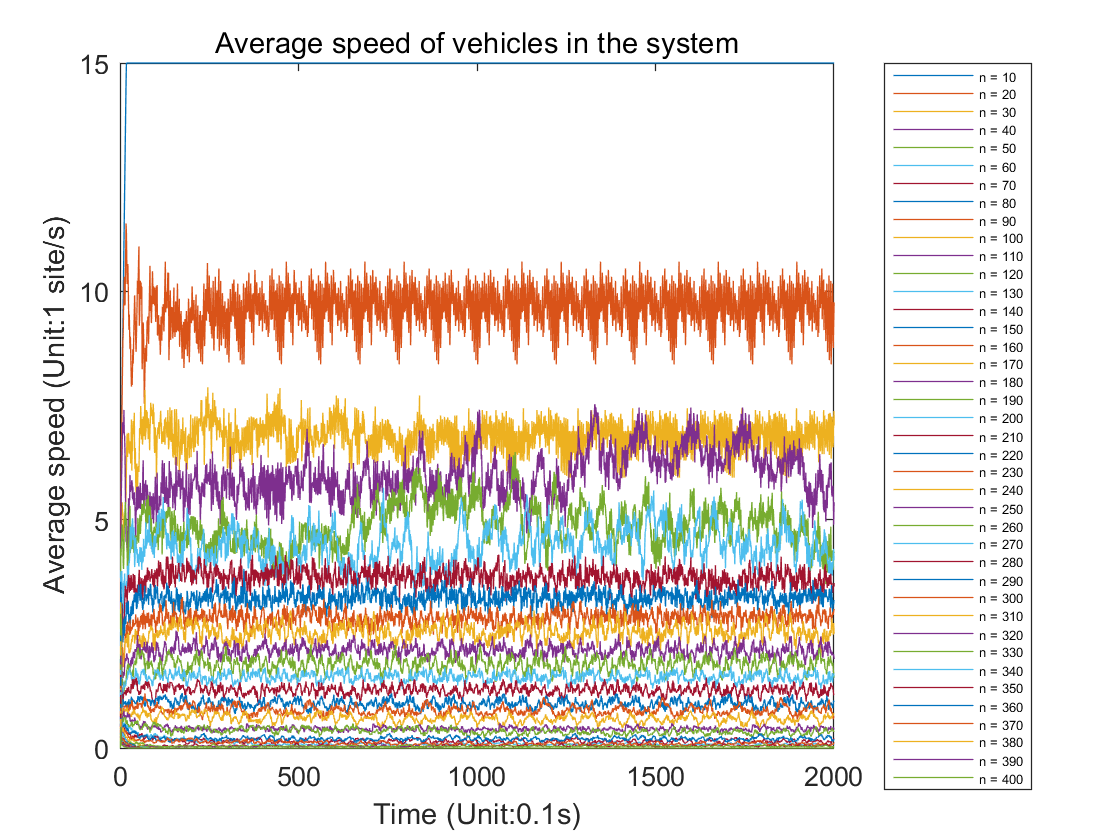

%时间调整xlim
for count=1:runtime
count1 = count*10;
plot(averageexa(count,:))
title("Average speed of vehicles in the system")
xlabel('Time (Unit:0.1s)')
ylabel('Average speed (Unit:1 site/s)')
xlim([0 2000])
hold on
legend_str{count} = ['n = ' num2str(count1)];
end
led = legend(legend_str);
set(led,'fontsize',5,'Location','bestoutside');

% for count=[4 5 6]
% plot(averageexa(count,:))
% title("Average speed of vehicles in the system")
% xlabel('Time (Unit:0.1s)')
% ylabel('Average speed (Unit:1 site/s)')
% xlim([0 10000])
% hold on
% end
% legend('n=40','n=50','n =60');
% legend('Location','bestoutside');